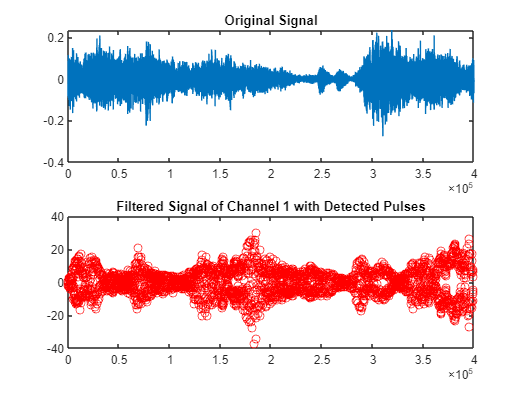

% Load audio file
[data, fs] = audioread('audio.wav');

% Load standard pulse
load('Pulse.mat'); % Assuming Pulse.mat contains the variable 'Pulse'

% Perform matched filtering on each channel
filtered_signals = zeros(size(data));
for i = 1:size(data, 2) % Iterate over each channel
    filtered_signals(:, i) = conv(data(:, i), yp, 'same');
end

% Find peaks in each channel
peak_threshold = 0.5; % Adjust as needed
peak_locs = cell(1, size(filtered_signals, 2));
for i = 1:size(filtered_signals, 2)
    [pks, locs] = findpeaks(abs(filtered_signals(:, i)), 'MinPeakHeight', peak_threshold);
    peak_locs{i} = locs;
end

% Determine which channel has more peaks (indicating the noise)
num_peaks = cellfun(@numel, peak_locs);
[~, noisy_channel] = max(num_peaks);

% Display detected pulse locations for the noisy channel
% disp(['Detected pulse locations in channel ', num2str(noisy_channel), ':']);
% disp(peak_locs{noisy_channel});

% Plot filtered signals with detected pulses
figure;
subplot(2, 1, 1);
plot(data(:, 1)); % Plot original signal
title('Original Signal');

subplot(2, 1, 2);
% plot(filtered_signals(:, noisy_channel)); % Plot filtered signal of the noisy channel
% hold on;
plot(peak_locs{noisy_channel}, filtered_signals(peak_locs{noisy_channel}, noisy_channel), 'ro'); % Mark detected pulses
title(['Filtered Signal of Channel ', num2str(noisy_channel), ' with Detected Pulses']);